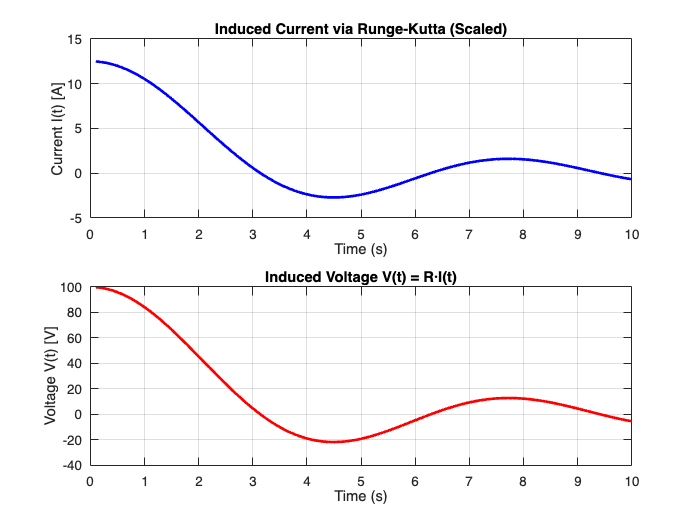

% Omar Verduzco Velazquez - A07019516
% Álvaro González Martínez - A01646343
% Rodrigo Armando Reveles Picie - A01641220
% Carlos Eduardo López Cuevas - A01640751
% Karlo Sebastián Cadena Cota - A00842489

clc; clear; close all;

R = 8;                     % Resistencia en ohms
A = 12.5;                  % Corriente
t0 = 0.1;                  % Tiempo inicial
tf = 10;                   % Tiempo final
h = 0.1;                   % Paso de integración
t = t0:h:tf;               % Vector de tiempo
I = zeros(size(t));        % Inicializar corriente (A)

% Condicion inicial
I(1) = A * sin(t0)/t0;

% Derivada
f = @(t) A * (t .* cos(t) - sin(t)) ./ (t.^2);

% Runge-Kutta 4to orden
for i = 1:length(t)-1
    k1 = h * f(t(i));
    k2 = h * f(t(i) + h/2);
    k3 = h * f(t(i) + h/2);
    k4 = h * f(t(i) + h);
    I(i+1) = I(i) + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
end

% Voltaje inducido en V
V = R * I;

% Graficar corriente
subplot(2,1,1);
plot(t, I, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Current I(t) [A]');
title('Induced Current via Runge-Kutta (Scaled)');
grid on;

% Graficar voltaje
subplot(2,1,2);
plot(t, V, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Voltage V(t) [V]');
title('Induced Voltage V(t) = R·I(t)');
grid on;


% Valor maximo voltaje 
fprintf('Máximo voltaje inducido: %.2f V\n', max(V));

Máximo voltaje inducido: 99.83 V
